# Anal3 matlab konzi, 2017. november 7.

syms x y z real

r = [x;y;z]

$$r = \left(\begin{array}{c} x\\ y\\ z \end{array}\right)$$

F = [
    y*z + 2
    x*z
    x*y
    ]

$$F = \left(\begin{array}{c} y\,z+2\\ x\,z\\ x\,y \end{array}\right)$$

potential(F,r)

$$ans = x\,\left(y\,z+2\right)$$

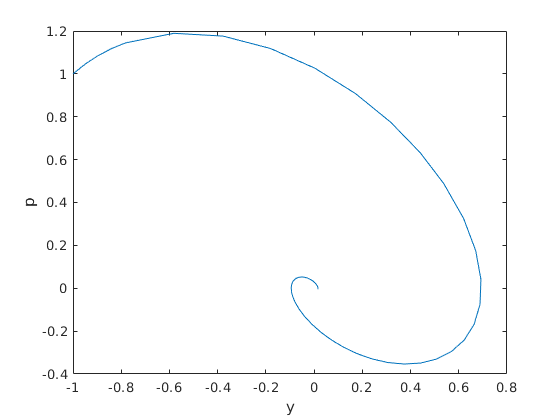

b = 1;
c = 1;
f = @(t,x) [
    x(2)
    -b * x(2) - c*x(1) + exp(-t)
    ];

x0 = [
    -1
    1
    ];

[t,x] = ode45(f, [0 10], x0);

plot(x(:,1),x(:,2))
xlabel y
ylabel p

syms t b c y p
x = [ y ; p ];

f = [
    p
    -b * p - c*y + exp(-t)
    ]

$$f = \left(\begin{array}{c} p\\ {\mathrm{e}}^{-t}-b\,p-c\,y \end{array}\right)$$

f = subs(f, [b c], [1 2])

$$f = \left(\begin{array}{c} p\\ {\mathrm{e}}^{-t}-2\,y-p \end{array}\right)$$

f_fh = matlabFunction(f,'vars',{ t x })

f_fh = function_handle with value:
    @(t,in2)[in2(2,:);-in2(2,:)-in2(1,:).*2.0+exp(-t)]

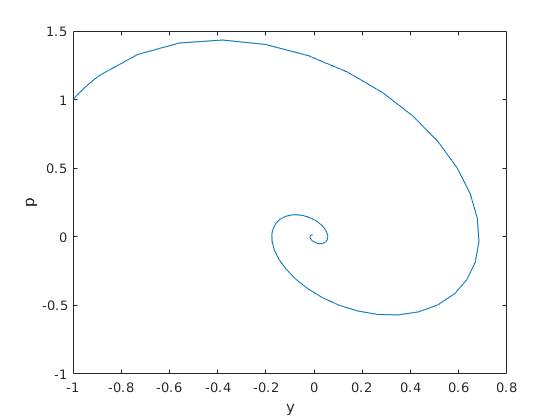

[t,x] = ode45(f_fh,[0,10],x0);
plot(x(:,1),x(:,2))
xlabel y
ylabel p

Numerikus integralas

f = @(x) x.^2;

integral(f,0,2)

ans = 2.6667

f = @(x,y) x.^2 + y.^2;
integral2(f,-1,1,@(x) -sqrt(1 - x.^2), @(x) sqrt(1 - x.^2))

ans = 1.5708

f = @(x,y,z) x.^2 + y.^2 + sin(z);
integral3(f,-1,1,@(x) -sqrt(1 - x.^2), @(x) sqrt(1 - x.^2), ...
    @(x,y) -sqrt(1 - x.^2 - y.^2), @(x,y) sqrt(1 - x.^2 - y.^2))

ans = 1.6755

f = @(y,x,z) x.^2 + y.^2 + sin(z);
integral3(f,-1,1,@(y) -sqrt(1 - y.^2), @(y) sqrt(1 - y.^2), ...
    @(y,x) -sqrt(1 - x.^2 - y.^2), @(y,x) sqrt(1 - x.^2 - y.^2))

ans = 1.6755

Szimbolikus integralas

syms x y z C real

f = 1 / sqrt(x^2/C^2 - 1)

$$f = \frac{1}{\sqrt{\frac{x^{2}}{C^{2}}-1}}$$

int(f,x), rewrite(acosh(x),'log')

$$ans = \log\left(x+\sqrt{x^{2}-C^{2}}\right)\,\sqrt{C^{2}}$$

$$ans = \log\left(x+\sqrt{x-1}\,\sqrt{x+1}\right)$$